PAL_st.name='PAL';
PAL_st.lat=67.97; 
PAL_st.lon=24.12;
PAL_st.alt=560;
PAL_st.env='P';
PAL_st.footp='RB';


PAL_rd=read_betsy('pal_2000_2017',PAL_st.name);

RH2007=table2timetable(nephrh2007);
RH2008=table2timetable(nephrh2008);
RH2010=table2timetable(nephrh2010);
RH2011=table2timetable(nephrh2011);
RH2010=retime(RH2010,'hourly','fillwithmissing');

% hourly RH > 50 =7 hours in July 2010 and 4 jour in March 2011:--> will
% not change the dry scattering much
%to simplify, just compute daily RH here

RH2007d=retime(RH2007,'daily', @nanmedian);
RH2008d=retime(RH2008,'daily', @nanmedian);
RH2010d=retime(RH2010,'daily', @nanmedian);
RH2011d=retime(RH2011,'daily', @nanmedian);


PAL_rd.y=year(PAL_rd.Time);
PAL_rd.U_S11(PAL_rd.y==2007)=RH2007d.relative_humidity;
PAL_rd.U_S11(PAL_rd.y==2008)=RH2008d.relative_humidity;
PAL_rd.U_S11(PAL_rd.y==2010)=RH2010d.relative_humidity;
PAL_rd.U_S11(PAL_rd.y==2011)=RH2011d.relative_humidity;

S07=read_nasa_ames_ebas('FI0096G.20070101.20190411.nephelometer.aerosol.1y.1h.FI01L_TSI3563.FI01L_NEPH.nas','\\meteoswiss.ch\mch\pay-prod\Aerosol_actris_trend\data\pal\');

 Reading: \\meteoswiss.ch\mch\pay-prod\Aerosol_actris_trend\data\pal\FI0096G.20070101.20190411.nephelometer.aerosol.1y.1h.FI01L_TSI3563.FI01L_NEPH.nas


S07T=timetable(datetime(datevec(S07.start_time)));
S07T.BsB=S07.aerosol_light_scattering_coefficient45;
S07T.BsG=S07.aerosol_light_scattering_coefficient55;
S07T.BsR=S07.aerosol_light_scattering_coefficient70;
S07T.BbsB=S07.aerosol_light_backscattering_coefficient45;
S07T.BbsG=S07.aerosol_light_backscattering_coefficient55;
S07T.BbsR=S07.aerosol_light_backscattering_coefficient70;
S_d=retime(S07T,"daily",@nanmedian);

datevec(PAL_rd.Time(1))

ans =         2000           2           3           0           0           0


datevec(PAL_rd.Time(end))

ans =         2018           1           1           0           0           0


prctile(PAL_rd.U_S11,[5 50 95])

ans =     3.4087   12.2000   31.7500


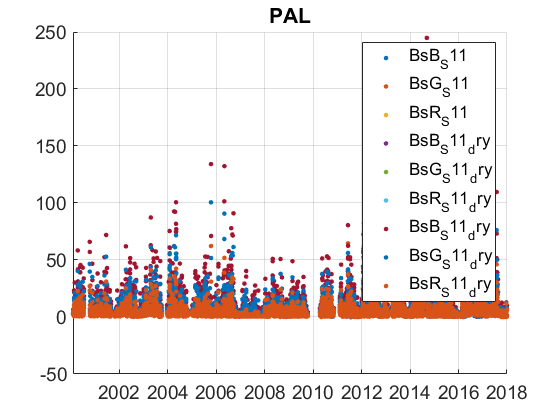

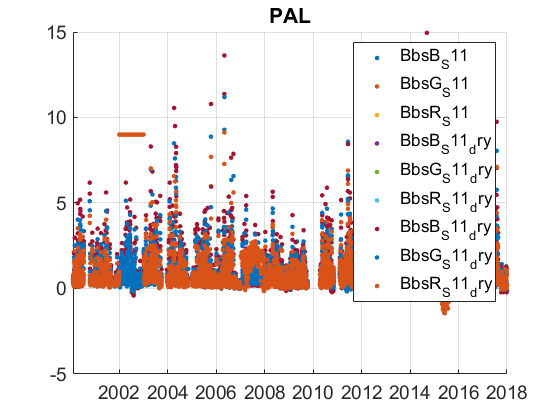

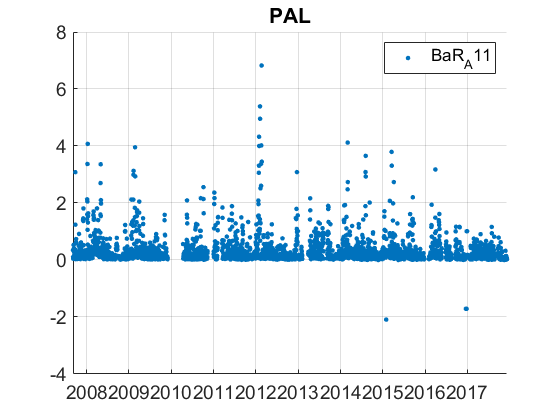

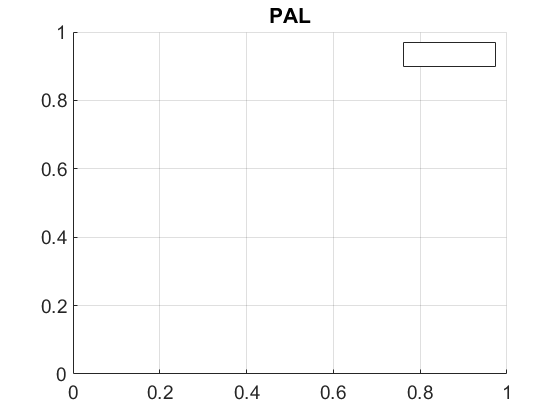

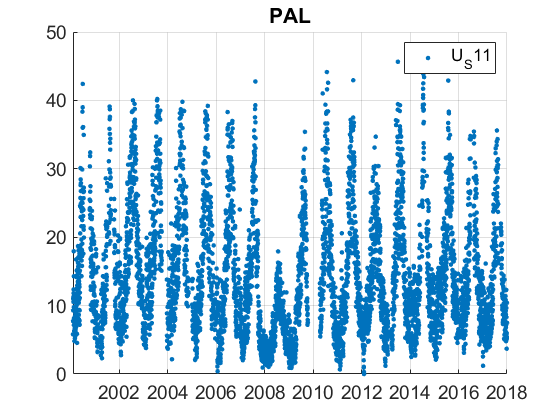

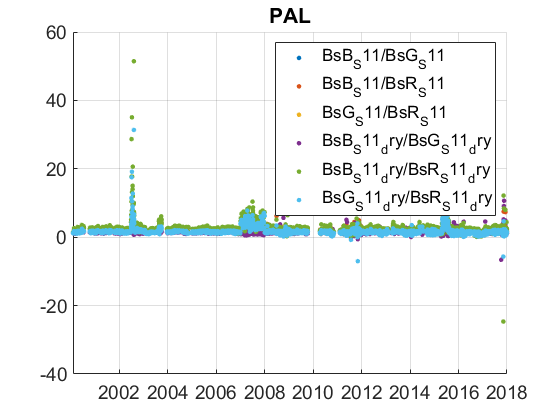

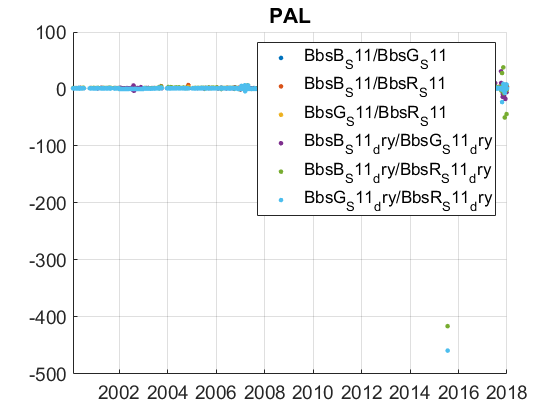

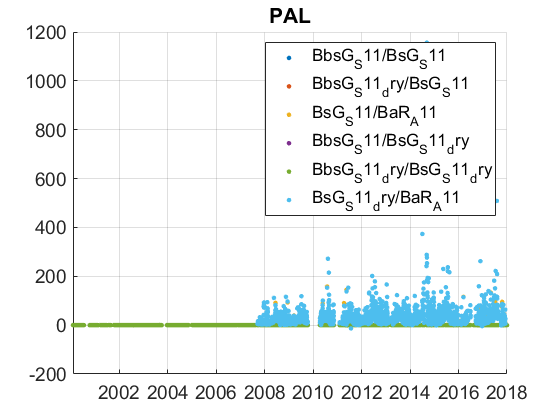


plotFigControl(PAL_rd,PAL_st.name);

% 1 size cut, 
% sc: ok, no clear seasonal cycle, no negatives
%abs: max in winter
%abs: change 1w to 3w end of 2005,change to CLAP in 2013 some negatives, abs maxima in winter
%abs: ratio between w: clear seasonal cycle, max in winter

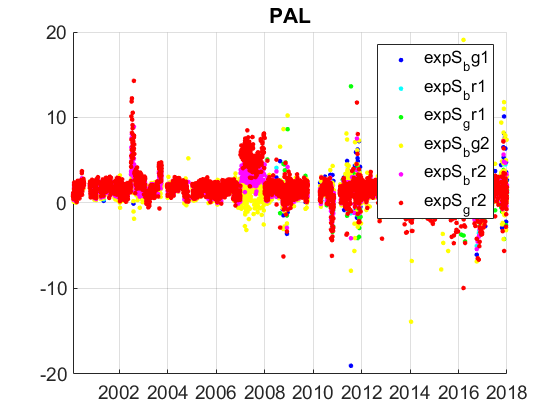

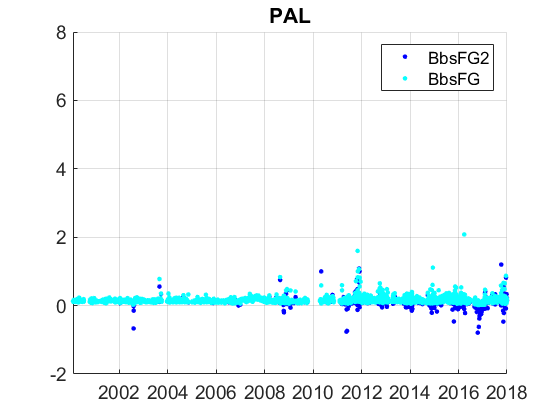

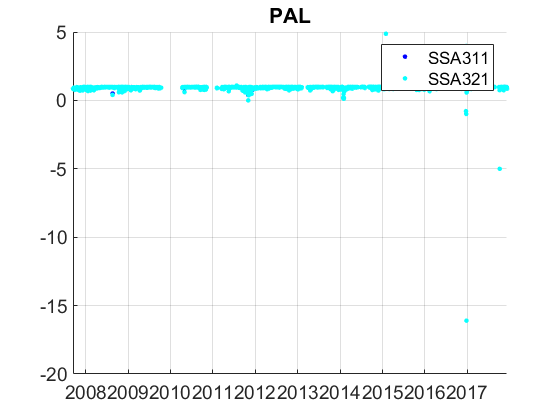

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
PAL_cal=compute_exp_SSA(PAL_rd,lambdaSC, lambdaAE);
plotFigControl_cal(PAL_cal, PAL_st.name);

% PAL_cal.SSA1_G=PAL_rd.BsG1_S./(PAL_rd.BsG1_S+PAL_rd.BaG1_A);
% PAL_cal.SSA0_G=PAL_rd.BsG0_S./(PAL_rd.BsG0_S+PAL_rd.BaG0_A);
% hold on;
% plot(PAL_rd.Time,SSA0_G,'.g');
% plot(PAL_rd.Time,SSA1_G,'.c');

%Questions:
%problems:

%RH: why there is no RH data in 2007, 2008, 2010, 2011 ? I just want to know if there is some RH change during that period or if it is as constant as for the whole time series ?

%scat: the maximal scattering at all wavelengths is lower from 2007 to 2011: was there any instrumental change/calibration?
% The red scattering has lower maxima and higher minima in 2007. This is not visible in the blue and green scat. What happened ?
%the red scat has higher minima from April 2016 to october 2017: Do you know the reason ?
%for your info, the green and red backscattering coefficients have false missing values (100) in 2002, 2005 and 2017.
%Backscattering: the green backscatter and to a lesser extend the blue one has higher mimima in 2007. The red backscatter has completely strange value in 2007 and is constant ==9 in 2002. What happened in 2007 and in 2002 ? 
% scattering exponent: when the red wavelength is involved, the scat exponent is too high in August 2002, September 2003, in 2007 and in June 2015. Do you have an explanation ?


%abs: seems ok

% it could be possible to use S_d taken directly from John file, but there
% is still difference with the end of the time series + no data at the end
% of 2007 --> I let it like it
PAL_tr=PAL_rd;
PAL_tr.y=year(PAL_tr.Time);
% begin at the beginning of a year: 2001 (2000??: ok it will not change the 10-15y,20y not possible anyhow since begin february)
%end: 2017
P=timerange('2000-01-01','2018-01-01');
PAL_tr=PAL_tr(P,:);
%take U_S since U1_S has no data in part of 2007, but U0 has some data less in 2013
%trend in RH have to be calculated since it changes
%few RH values > 50%, only at the beginning where scat= NaN: few difference, don't use dry
names=fieldnames(PAL_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"Uu";"U1"]) | endsWith(names,'dry') | contains(names,'Q');
N=names(c);
for i=1:length(N)
    PAL_tr.(N{i})=[];
end

%abs period: 2008-2017: remove 2007 data
%abs: AE begin in 2006 for a whole year --> 2 y more than MAAP. Ask for AE?
P1=timerange('2000-01-01','2008-01-01');
PAL_tr.BaR_A11(P1)=NaN;

%scat exp: use the BG 

%correct abs for green wavelength to compute SSA
PAL_tr.BaR_A11= PAL_tr.BaR_A11.*(637/550);
% % %take green-red SSA
 PAL_cal2=compute_exp_SSA(PAL_tr,lambdaSC, lambdaAE);

% % PAL_cal2.SSA0G=PAL_tr.BsG0_S./(PAL_tr.BsG0_S+PAL_tr.BaG0_A);
% % PAL_cal2.SSA1G=PAL_tr.BsG1_S./(PAL_tr.BsG1_S+PAL_tr.BaG1_A);
% % plotFigControl_cal(PAL_cal2,PAL_st.name);
 PAL_tr=outerjoin(PAL_tr, PAL_cal2);
   
% % PAL_tr.SSA011=[];
% % PAL_tr.SSA111=[];

%compute trend on G
PAL_tr.BsB_S11=[];
PAL_tr.BsR_S11=[];
PAL_tr.BbsB_S11=[];
PAL_tr.BbsR_S11=[];
%only expS bg
PAL_tr.expS_br3=[];
PAL_tr.expS_gr3=[];

PAL_result= all_trend_STN(PAL_tr,PAL_st); 
plot_10y_in_two(PAL_result, PAL_st);
% PAL_tr2=timetable(PAL_tr.Time);
% PAL_tr2.y=PAL_tr.y;
% PAL_tr2.SSA=PAL_tr.SSA311;
% 
% PAL_result2= all_trend_STN(PAL_tr2,PAL_st); 

PAL_result_D=PAL_result;

PAL_tr2=PAL_tr;
%try without 2008 for rh and neph due to very low humidity
P3=timerange('2008-01-01','2009-01-01');
names=fieldnames(PAL_tr);
c= startsWith(names,["Bs";"Bbs";"U_"]);
N=names(c);
for i=1:length(N)
    PAL_tr2.(N{i})(P3)=NaN;
end
PAL_st2=PAL_st;
PAL_st2.name='PAL2';

PAL_result2= all_trend_STN(PAL_tr2,PAL_st2);
